e_n = eye(2);
n = size(e_n, 2);
Nmax = 100;
%deklaracja funkcji
f=@(x1,x2)2.5*(x1.^2-x2).^2+(1-x1).^2 

f = function_handle with value:
    @(x1,x2)2.5*(x1.^2-x2).^2+(1-x1).^2


f_ = @(x)2.5*(x(1).^2-x(2)).^2+(1-x(1)).^2 ;
P =[0.25,0.5];
P1 = [-0.1,-0.1];
epsilon = 1e-5;



[x, it] = Powell(f, P1, e_n, n, Nmax, epsilon)

x =     1.0000    1.0000


it = 4

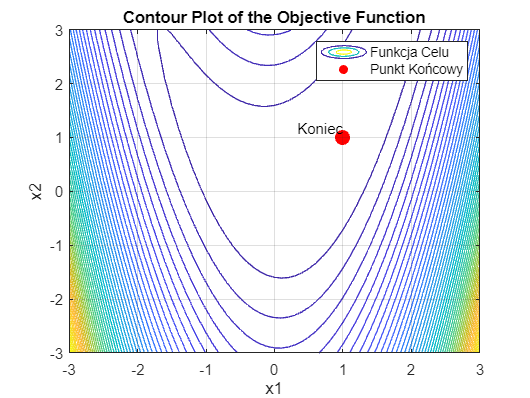

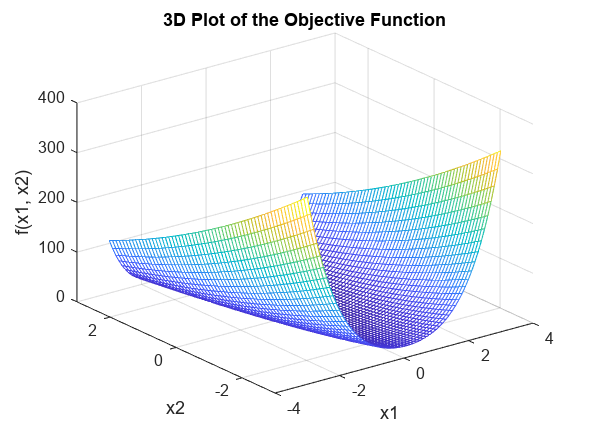


plot_result(f, x)


f= @(x1, x2) 0.3*x1+0.1*x2+(-3.5+0.5*x1.^2+0.5*x2.^2).^2+100*x1 .* exp(-x1.^2 - x2.^2)

f = function_handle with value:
    @(x1,x2)0.3*x1+0.1*x2+(-3.5+0.5*x1.^2+0.5*x2.^2).^2+100*x1.*exp(-x1.^2-x2.^2)


P0=[1,0];
P1=[-2,-2];
e_n1 = [1 -1; 1 1];
[x, it] = Powell(f, P0, e_n1, n, Nmax, epsilon)

x =    -2.4540   -0.5025


it = 10

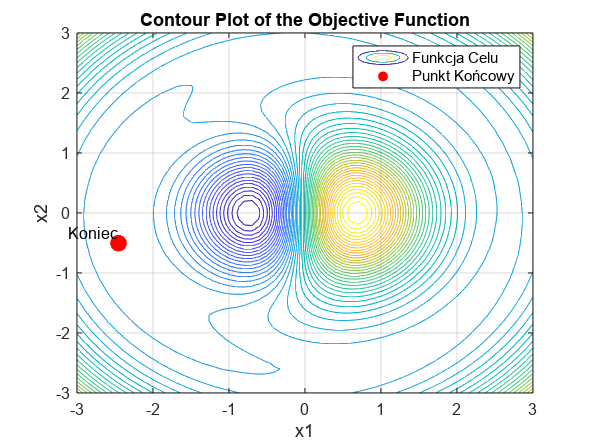

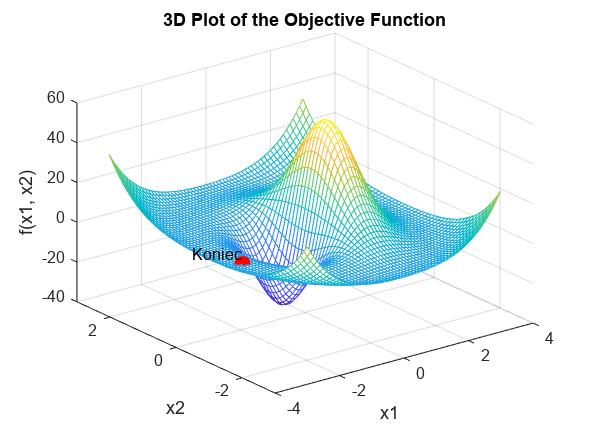

plot_result(f, x)

function [] = plot_result(f, x)
figure;
[X, Y] = meshgrid(-3:0.1:3, -3:0.1:3);
Z = f(X, Y);
contour(X, Y, Z, 50);
title('Contour Plot of the Objective Function');
xlabel('x1');
ylabel('x2');
hold on;

% Oznacz punkt końcowy na wykresie konturów
scatter(x(end, 1), x(end, 2), 100, 'r', 'filled');
text(x(end, 1), x(end, 2), '  Koniec', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

legend('Funkcja Celu', 'Punkt Końcowy');
grid on;
hold off;

% Wykres 3D funkcji celu
figure;
mesh(X, Y, Z);
hold on;

% Oznacz punkt końcowy na wykresie 3D
scatter3(x(end, 1), x(end, 2), f(x(end, 1), x(end, 2)), 100, 'r', 'filled');
text(x(end, 1), x(end, 2), f(x(end, 1), x(end, 2)), '  Koniec', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

title('3D Plot of the Objective Function');
xlabel('x1');
ylabel('x2');
zlabel('f(x1, x2)');
grid on;
hold off;

end

function [result, i] = Powell(f, x, d, n, Nmax, epsilon)
    syms alfa
    i = 1;
    p = [];
    while i < Nmax
        p(i, :) = x;
        for j = 1 : 1: n
            d_j = d(:, j)';
            p1 = p(i + j - 1, :) + alfa*d_j;
            alfa_j = findmin_alfa(f, p1);
            p(i+j,:) = p(i + j - 1, :) + alfa_j* d_j;
        end
        p_n = p(n + i, :);
        if abs(f(p_n(1), p_n(2)) - f(x(1), x(2))) < epsilon
            result = p(n + i, :);
            return;
        end
        for j = 1 : 1 : n-1
            d(:, j) = d(:, j+1);
        end
        d(:, n) = p(n + i, :)' - p(i, :)';
        d_n = d(:, n)';
        p_np1 = p(n + i, :) + alfa*d_n;
        alfa_n = findmin_alfa(f, p_np1);
        p(n + i + 1, :) = p(n + i, :) + alfa_n*d_n;
        x = p(n + i + 1, :);
        i = i + 1;
    end
    result = x;

end

function [alfa] = findmin_alfa(f, p1)
    syms alfa x
    g_alfa = f(p1(1), p1(2));
    fun = subs(g_alfa, alfa, x);
    fun = matlabFunction(fun);
    alfa = fminsearch(fun, 0);
end
